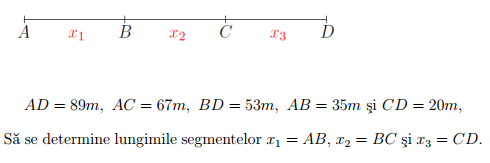

Avand masuratorile facute, se poate vedea ca sistemul este supradeterminat, avand mai multe ecuatii decat necunoscute. Putem considera problema in functie de care segmente sunt utilizate, pentru a forma matricea de caracteristici:

$AD = x_1 + x_2 + x_3;\\
AC = x_1 + x_2;\\
BD = x_2 + x_3;\\
AB = x_1;\\
CD = x_3;$, iar matricile sunt acestea:

$A = \left[\matrix{1 & 1 & 1 \cr 1 & 1 & 0 \cr 0 & 1 & 1 \cr 1 & 0 & 0 \cr 0 & 0 & 1}\right]$ si $b = \left[\matrix{89 & 67 & 53 & 35 & 20}\right]^T$

A = [1 1 1;
     1 1 0;
     0 1 1;
     1 0 0;
     0 0 1];
b = [89; 67; 53; 35; 20];

target = [35; 33; 20];

x = A \ b;

fprintf("x1 (AB) = %.4f\n", x(1));

x1 (AB) = 35.1250


fprintf("x2 (BC) = %.4f\n", x(2));

x2 (BC) = 32.5000


fprintf("x3 (CD) = %.4f\n", x(3));

x3 (CD) = 20.6250



fprintf("### RSS: %.4f\n", residual_sum_squares(x, target));

### RSS: 0.6562


fprintf("### R^2: %.4f\n", coefficient_of_det(x, target));

### R^2: 0.9951
